## Controlo Automático - Projecto

%% Inicialização do ambiente
clear ; close all; clc

% Importamos os dados dos pacientes
data = importdata('ROC_REAL_50.mat');

% Definimos uma seed estatica para o gerador de números aleatórios de forma
% a podermos repetir os experimentos com resultados determinísticos
rng(42);

### **Questão 1**

**a)** Selecionamos 10 pacientes da base de dados:

rndIDX = randperm(50);
sample = data(rndIDX(1:10), :)

sample =     0.0219    1.2746
    0.0528    2.5362
    0.0352    1.5503
    0.0293    1.4728
    0.0308    1.9499
    0.0330    2.4823
    0.0282    1.2615
    0.0295    1.2390
    0.0329    2.5669
    0.0394    2.0425


**b) e c)**

Cálculo de $c_e \left(t\right)$ e da respectiva média.

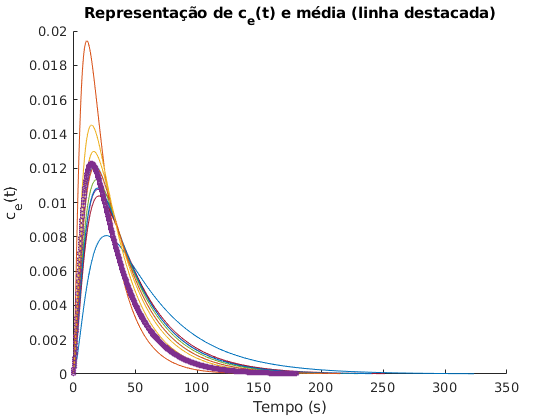

figure(1);
hold on
Ce = [];
for row = 1 : length(sample)
    a = sample(row,1);
    s = tf('s');
    G = (40*a^3)/((s+a)*(s+4*a)*(s+10*a));
    % Plot
    [y,t] = impulse(G * 0.6);
    plot(t,y)
    % Save the data
    Ce = [Ce, impulse(G * 0.6)];
end
plot(t, mean(Ce, 2), 'h','MarkerSize',4)
xlabel('Tempo (s)')
ylabel('c_{e}(t)')
title('Representação de c_{e}(t) e média (linha destacada)')
hold off

% Remover a primeira linha de zeros do Ce
Ce = Ce(2:end,:);

Cálculo de $R\left(t\right)$ e da respectiva média.

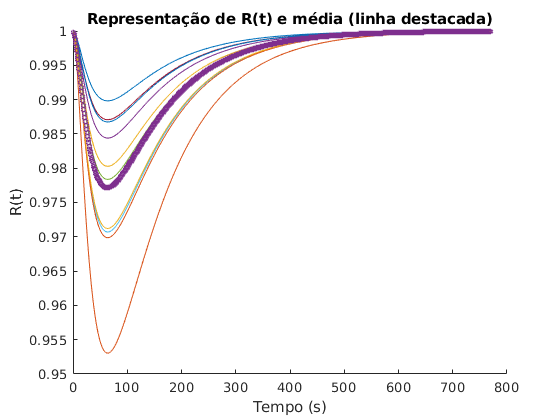

r0 = 1;
EC50 = 1;
figure(2);
hold on
R_collection = [];
for row = 1 : length(sample)
    gamma = sample(row,2);
    R = r0 ./ (1 + (Ce(:, row) / EC50) * gamma);
    R_collection = [R_collection, R];
    plot(R);
end
% Remover a primeira linha de zeros do R_collection
R_collection = R_collection(2:end,:);
plot(mean(R_collection, 2), 'h','MarkerSize',4)
xlabel('Tempo (s)')
ylabel('R(t)')
title('Representação de R(t) e média (linha destacada)')
hold off

### **Questão 2**

Para calcularmos a estabilidade, recorremos ao critério de estabilidade de Routh-Hurwitz, para isso adaptamos: *Farzad Sagharchi (2020). Routh-Hurwitz stability criterion (https://www.mathworks.com/matlabcentral/fileexchange/17483-routh-hurwitz-stability-criterion), MATLAB Central File Exchange. Retrieved May 25, 2020.* (código alterado em *rhcalculator.m*).

fprintf('Vamos tomar como vector de coeficientes possível representante do nosso sistema o seguinte:\n')

Vamos tomar como vector de coeficientes possível representante do nosso sistema o seguinte:


a = sample(1,1);
coeffVector = [(1+a) (1+4*a) (1+10*a)]

coeffVector =     1.0219    1.0877    1.2193



rhcalculator

fprintf('Tabela de Routh-Hurwitz:\n')

Tabela de Routh-Hurwitz:


rhTable

rhTable =     1.0219    1.2193
    1.0877         0
    1.2193         0



% Análise da estabilidade
if unstablePoles == 0
    fprintf('É um sistema estável.\n')
else
    fprintf('É um sistema instável!\n')
end

É um sistema estável.



fprintf('Número de polos no lado direito =%2.0f\n', unstablePoles)

Número de polos no lado direito = 0



sysRoots = roots(coeffVector);
fprintf('Raizes dos coeficientes do polinómio em causa :\n')

Raizes dos coeficientes do polinómio em causa :


sysRoots

sysRoots =   -0.5322 + 0.9539i
  -0.5322 - 0.9539i
